# 变分法和动态规划

## 问题一

在下图中，求A点到E点的最短路线和最短路程。（逆序、顺序）

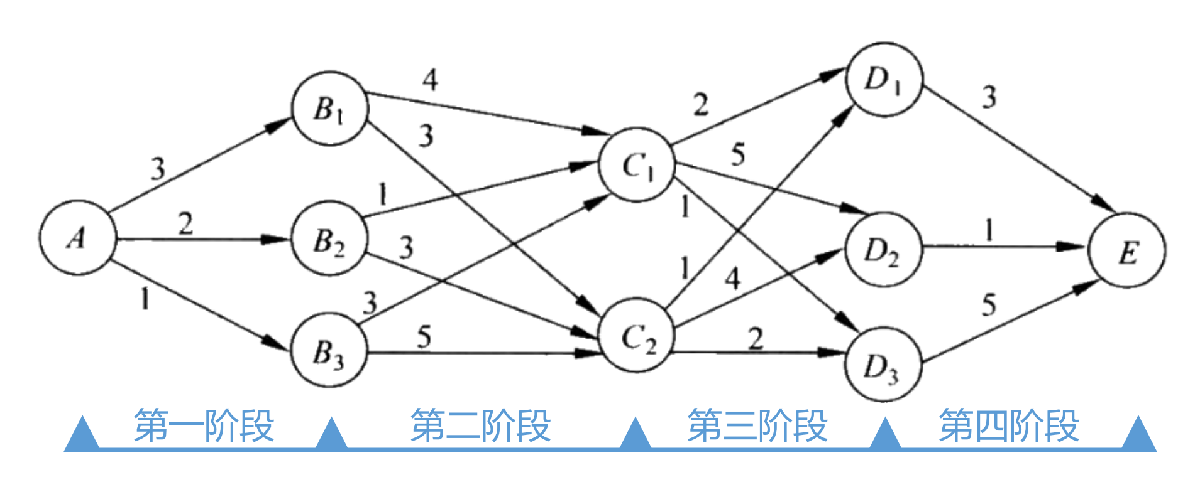

答案：A-B2-C1-D1-E

上已有算法，美吱吱~

% 源节点
s=[1 1 1 2 2 3 3 4 4 5 5 5 6 6 6 7 8 9];
% 目标节点
t=[2 3 4 5 6 5 6 5 6 7 8 9 7 8 9 10 10 10];
% 权重
w=[3 2 1 4 3 1 3 3 5 2 5 1 1 4 2 3 1 5];
% 名称
names=["A" "B1" "B2" "B3" "C1" "C2" "D1" "D2" "D3" "E"];
G=digraph(s,t,w,names)

G =   digraph - 属性:

    Edges: [18×2 table]
    Nodes: [10×1 table]


p=plot(G,'EdgeLabel',G.Edges.Weight);
P=shortestpath(G,"A","E")

P = 1×5 string 数组
    "A"    "B2"    "C1"    "D1"    "E"


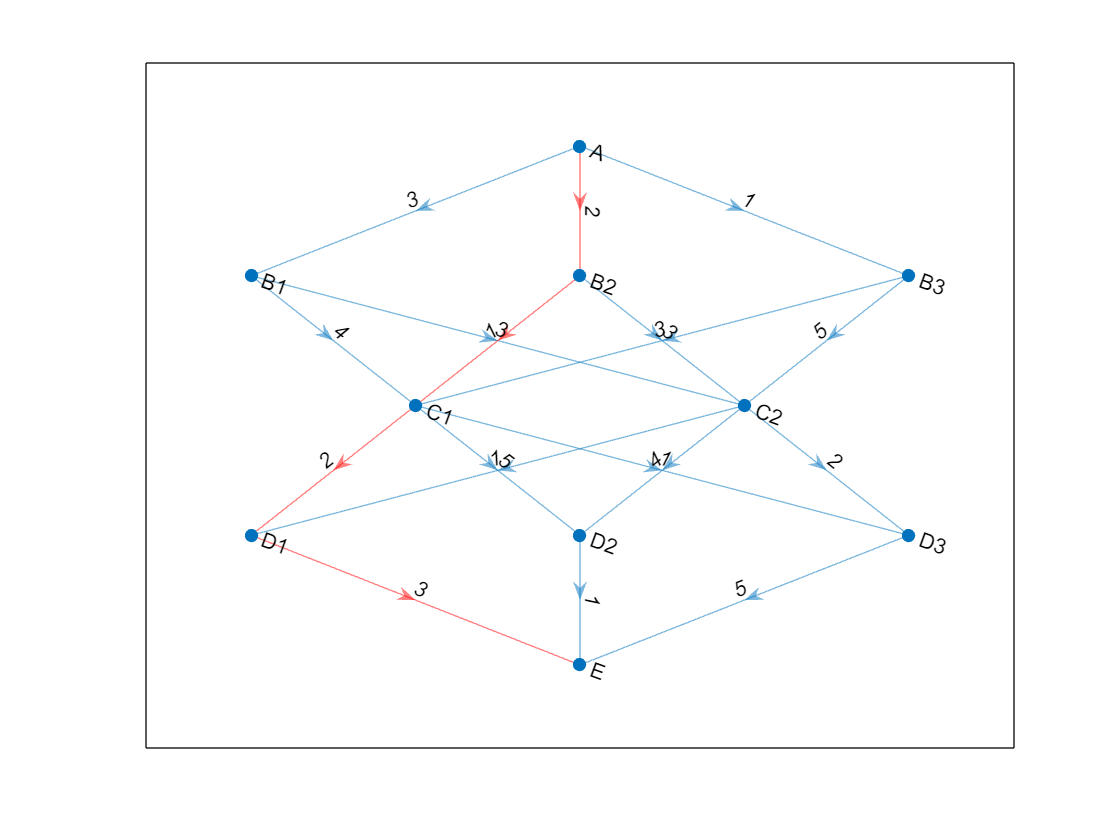

highlight(p,P,'EdgeColor','red')

轻轻松松！